fs = 2.5e5;
w = floor(11*fs/1000);
overlap = floor(8*fs/1000);





[S,fMel,tMel] = melSpectrogram(vec,2.5e5, ...
    'WindowLength',2750,...
    'OverlapLength',2000, ...
    'FFTLength',5500, ...
    'NumBands',124, ...
    'FrequencyRange',[1000 125000]);
[s,f,t] = spectrogram(vec,hamming(512),256,512,2.5e5,'yaxis');
s = log(abs(s)+eps);

d = (abs(tMel-t));
[~,indT] = min(d,[],2);

fd = (abs(fMel'-f'));
[~,indF] = min(fd,[],2);

[Xmel,Ymel] = meshgrid(tMel,fMel);

pointsSet1 = [Xmel(:)';Ymel(:)'];
pointsSet2 = [X(:)';Y(:)'];

%Translater
newImg = zeros(size(s));
% [X,Y] = meshgrid((indT),(indF));
ind = sub2ind(size(s),Y(:)',X(:)');
newImg(ind') = k(:);
newImg = imgaussfilt(newImg.*50,[10,10]);
newImg(newImg>1) = 1;

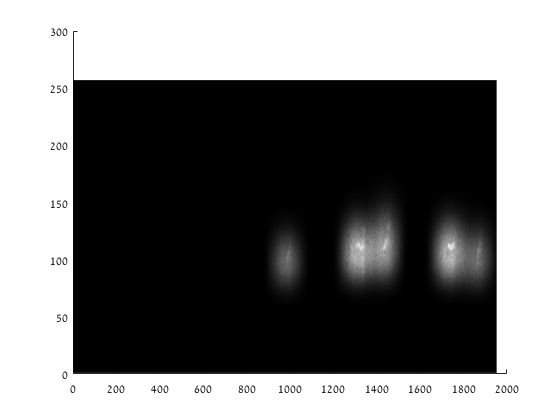

sN = s-min(s,[], "all");
I_copy = newImg.*sN;
I_copy = medfilt2(I_copy,[2,2]);
I_copy = imsharpen(I_copy);
plotSurface(I_copy)